# System 1

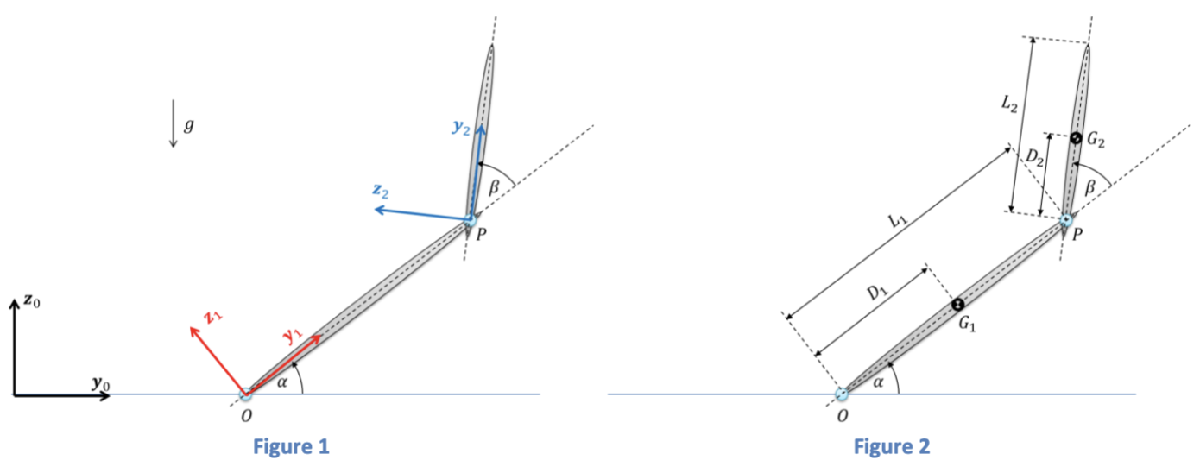

clc; clear;
% Symbolic Variables:
syms t alpha(t) beta(t)
syms D_1 D_2 L_1 L_2
syms m_1 m_2
syms I_1x I_1y I_1z I_2x I_2y I_2z

I_1_G1_1 = diag([I_1x, I_1y, I_1z]);
I_2_G2_2 = diag([I_2x, I_2y, I_2z]);



## 1) Setup Frames

## 2) Angular Velocities

$$R01 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\alpha \left(t\right)\right) & -\sin\left(\alpha \left(t\right)\right)\\ 0 & \sin\left(\alpha \left(t\right)\right) & \cos\left(\alpha \left(t\right)\right) \end{array}\right)$$

$$R10 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\alpha \left(t\right)\right) & \sin\left(\alpha \left(t\right)\right)\\ 0 & -\sin\left(\alpha \left(t\right)\right) & \cos\left(\alpha \left(t\right)\right) \end{array}\right)$$

$$R12 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\beta \left(t\right)\right) & -\sin\left(\beta \left(t\right)\right)\\ 0 & \sin\left(\beta \left(t\right)\right) & \cos\left(\beta \left(t\right)\right) \end{array}\right)$$

$$R21 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\beta \left(t\right)\right) & \sin\left(\beta \left(t\right)\right)\\ 0 & -\sin\left(\beta \left(t\right)\right) & \cos\left(\beta \left(t\right)\right) \end{array}\right)$$

## 3) Position Vectors

## 4) Velocity and Acceleration Vectors

syms alpha_dot(t) beta_dot(t) alpha_ddot beta_ddot % not functions of time, for later

$$w1\_1(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\alpha \left(t\right)\\ 0\\ 0 \end{array}\right)$$

$$w21\_1(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\beta \left(t\right)\\ 0\\ 0 \end{array}\right)$$

$$w2\_1(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\alpha \left(t\right)+\frac{\partial }{\partial t}\beta \left(t\right)\\ 0\\ 0 \end{array}\right)$$

$$w2\_2(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\alpha \left(t\right)+\frac{\partial }{\partial t}\beta \left(t\right)\\ 0\\ 0 \end{array}\right)$$

## 5) Angular Momentum

## 6) FBDs

Link 1

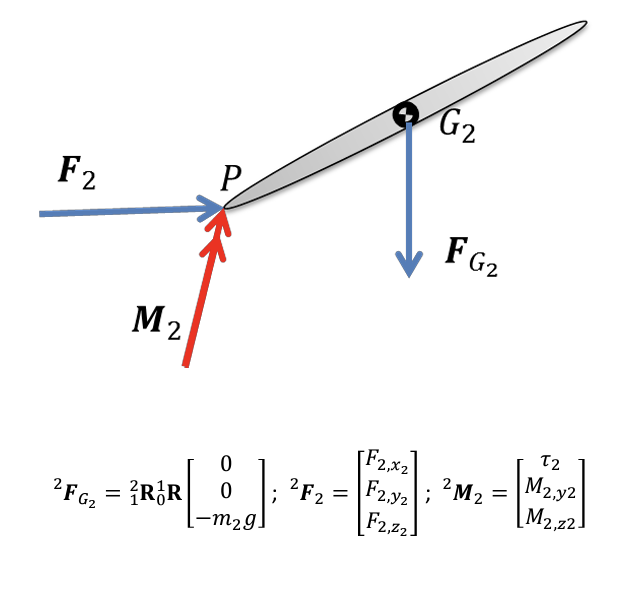

syms F2x F2y F2z tau_2 M2y M2z g

$$rOG1\_1 = \left(\begin{array}{c} 0\\ D_{1}\\ 0 \end{array}\right)$$

$$rOP\_1 = \left(\begin{array}{c} 0\\ L_{1}\\ 0 \end{array}\right)$$

$$rPG2\_2 = \left(\begin{array}{c} 0\\ D_{2}\\ 0 \end{array}\right)$$

$$rOG2\_2 = \left(\begin{array}{c} 0\\ D_{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\\ -L_{1}\,\sin\left(\beta \left(t\right)\right) \end{array}\right)$$

Link 2

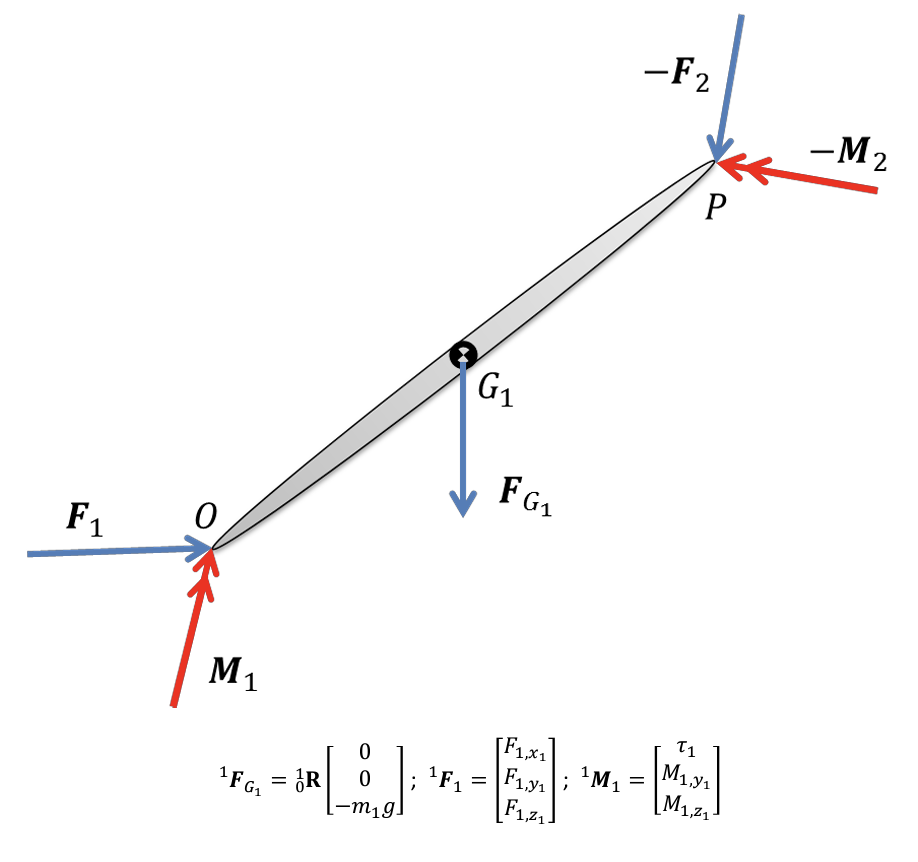

syms F1x F1y F1z tau_1 M1y M1z



$$rOG1\_dot\_1\_subs(t) = \left(\begin{array}{c} 0\\ 0\\ D_{1}\,\dot{\alpha }\left(t\right) \end{array}\right)$$

$$rOG2\_dot\_2\_subs(t) = \left(\begin{array}{c} 0\\ L_{1}\,\sin\left(\beta \left(t\right)\right)\,\left(\dot{\alpha }\left(t\right)+\dot{\beta }\left(t\right)\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,\dot{\beta }\left(t\right)\\ \left(\dot{\alpha }\left(t\right)+\dot{\beta }\left(t\right)\right)\,\left(D_{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\right)-L_{1}\,\cos\left(\beta \left(t\right)\right)\,\dot{\beta }\left(t\right) \end{array}\right)$$

$$rOG1\_ddot\_1\_subs(t) = \left(\begin{array}{c} 0\\ -D_{1}\,{\dot{\alpha }\left(t\right)}^{2}\\ D_{1}\,\ddot{\alpha } \end{array}\right)$$

$$rOG2\_ddot\_2\_subs(t) = \left(\begin{array}{c} 0\\ L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)-D_{2}\,{\dot{\beta }\left(t\right)}^{2}-L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}-2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-D_{2}\,{\dot{\alpha }\left(t\right)}^{2}\\ L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right) \end{array}\right)$$

## Isolating Equations

$$h\_G1\_link1\_1(t) = \left(\begin{array}{c} I_{\mathrm{1x}}\,\dot{\alpha }\left(t\right)\\ 0\\ 0 \end{array}\right)$$

$$h\_G1\_link1\_dot\_1\_subs(t) = \left(\begin{array}{c} I_{\mathrm{1x}}\,\ddot{\alpha }\\ 0\\ 0 \end{array}\right)$$

$$h\_G2\_link2\_2(t) = \left(\begin{array}{c} I_{\mathrm{2x}}\,\left(\dot{\alpha }\left(t\right)+\dot{\beta }\left(t\right)\right)\\ 0\\ 0 \end{array}\right)$$

$$h\_G2\_link2\_dot\_2\_subs(t) = \left(\begin{array}{c} I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)\\ 0\\ 0 \end{array}\right)$$

$$F\_G\_2 = \left(\begin{array}{c} 0\\ -g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\\ -g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}\right)$$

$$F2\_2 = \left(\begin{array}{c} \mathrm{F2x}\\ \mathrm{F2y}\\ \mathrm{F2z} \end{array}\right)$$

$$M2\_2 = \left(\begin{array}{c} \tau_{2}\\ \mathrm{M2y}\\ \mathrm{M2z} \end{array}\right)$$

$$p\_link2\_dot\_2(t) = \left(\begin{array}{c} 0\\ -m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)\right)\\ m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right) \end{array}\right)$$

$$sum\_F = \left(\begin{array}{c} \mathrm{F2x}\\ \mathrm{F2y}-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\\ \mathrm{F2z}-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}\right)$$

$$linear(t) = \left(\begin{array}{c} 0=\mathrm{F2x}\\ -m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)=\mathrm{F2y}-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\\ m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)=\mathrm{F2z}-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}\right)$$

$$F2x\_sol = 0$$

$$F2y\_sol = g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)-m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)$$

$$F2z\_sol = m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)$$

$$F2\_2 = \left(\begin{array}{c} 0\\ g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)-m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)\\ m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}\right)$$

$$rG2P\_2 = \left(\begin{array}{c} 0\\ -D_{2}\\ 0 \end{array}\right)$$

$$sum\_M = \left(\begin{array}{c} \tau_{2}-D_{2}\,\left(m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)\right)\\ \mathrm{M2y}\\ \mathrm{M2z} \end{array}\right)$$

$$angular(t) = \left(\begin{array}{c} I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)=\tau_{2}-D_{2}\,\left(m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)\right)\\ 0=\mathrm{M2y}\\ 0=\mathrm{M2z} \end{array}\right)$$

$$tau\_2\_sol = D_{2}\,\left(m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)\right)+I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)$$

$$M2y\_sol = 0$$

$$M2z\_sol = 0$$

$$M2\_2 = \left(\begin{array}{c} D_{2}\,\left(m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)\right)+I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)\\ 0\\ 0 \end{array}\right)$$

$$eom1 = \tau_{2}=D_{2}\,\left(m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\cos\left(\alpha \left(t\right)+\beta \left(t\right)\right)\right)+I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)$$

$$F\_G\_1 = \left(\begin{array}{c} 0\\ -g\,m_{1}\,\sin\left(\alpha \left(t\right)\right)\\ -g\,m_{1}\,\cos\left(\alpha \left(t\right)\right) \end{array}\right)$$

$$F1\_1 = \left(\begin{array}{c} \mathrm{F1x}\\ \mathrm{F1y}\\ \mathrm{F1z} \end{array}\right)$$

$$M1\_1 = \left(\begin{array}{c} \tau_{1}\\ \mathrm{M1y}\\ \mathrm{M1z} \end{array}\right)$$

$$sumF = \begin{array}{l} \left(\begin{array}{c} \mathrm{F1x}\\ \mathrm{F1y}+\cos\left(\beta \left(t\right)\right)\,\sigma_{1}+\sin\left(\beta \left(t\right)\right)\,\sigma_{2}-g\,m_{1}\,\sin\left(\alpha \left(t\right)\right)\\ \mathrm{F1z}-\cos\left(\beta \left(t\right)\right)\,\sigma_{2}+\sin\left(\beta \left(t\right)\right)\,\sigma_{1}-g\,m_{1}\,\cos\left(\alpha \left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\\ \sigma_{2}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}$$

$$p\_link1\_dot\_1(t) = \left(\begin{array}{c} 0\\ -D_{1}\,m_{1}\,{\dot{\alpha }\left(t\right)}^{2}\\ D_{1}\,\ddot{\alpha }\,m_{1} \end{array}\right)$$

$$linear(t) = \begin{array}{l} \left(\begin{array}{c} 0=\mathrm{F1x}\\ -D_{1}\,m_{1}\,{\dot{\alpha }\left(t\right)}^{2}=\mathrm{F1y}+\cos\left(\beta \left(t\right)\right)\,\sigma_{1}+\sin\left(\beta \left(t\right)\right)\,\sigma_{2}-g\,m_{1}\,\sin\left(\alpha \left(t\right)\right)\\ D_{1}\,\ddot{\alpha }\,m_{1}=\mathrm{F1z}-\cos\left(\beta \left(t\right)\right)\,\sigma_{2}+\sin\left(\beta \left(t\right)\right)\,\sigma_{1}-g\,m_{1}\,\cos\left(\alpha \left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\\ \sigma_{2}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}$$

$$F1x\_sol = 0$$

$$F1y\_sol = g\,m_{1}\,\sin\left(\alpha \left(t\right)\right)-\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)\right)-D_{1}\,m_{1}\,{\dot{\alpha }\left(t\right)}^{2}-\cos\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)$$

$$F1z\_sol = \cos\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)\right)-\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)+D_{1}\,\ddot{\alpha }\,m_{1}$$

$$F1\_1 = \begin{array}{l} \left(\begin{array}{c} 0\\ g\,m_{1}\,\sin\left(\alpha \left(t\right)\right)-\sin\left(\beta \left(t\right)\right)\,\sigma_{2}-D_{1}\,m_{1}\,{\dot{\alpha }\left(t\right)}^{2}-\cos\left(\beta \left(t\right)\right)\,\sigma_{1}\\ \cos\left(\beta \left(t\right)\right)\,\sigma_{2}-\sin\left(\beta \left(t\right)\right)\,\sigma_{1}+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)+D_{1}\,\ddot{\alpha }\,m_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\\ \sigma_{2}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}$$

$$sum\_M = \begin{array}{l} \left(\begin{array}{c} \tau_{1}-D_{2}\,\sigma_{3}-D_{1}\,\left(\sigma_{2}-\sigma_{1}+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)+D_{1}\,\ddot{\alpha }\,m_{1}\right)-I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)-\left(\sigma_{2}-\sigma_{1}\right)\,\left(D_{1}-L_{1}\right)\\ \mathrm{M1y}\\ \mathrm{M1z} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)\\ \sigma_{2}=\cos\left(\beta \left(t\right)\right)\,\sigma_{3}\\ \sigma_{3}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}$$

$$angular(t) = \begin{array}{l} \left(\begin{array}{c} I_{\mathrm{1x}}\,\ddot{\alpha }=\tau_{1}-D_{2}\,\sigma_{3}-D_{1}\,\left(\sigma_{2}-\sigma_{1}+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)+D_{1}\,\ddot{\alpha }\,m_{1}\right)-I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)-\left(\sigma_{2}-\sigma_{1}\right)\,\left(D_{1}-L_{1}\right)\\ 0=\mathrm{M1y}\\ 0=\mathrm{M1z} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)\\ \sigma_{2}=\cos\left(\beta \left(t\right)\right)\,\sigma_{3}\\ \sigma_{3}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}$$

$$tau\_1\_sol = \begin{array}{l} I_{\mathrm{1x}}\,\ddot{\alpha }+D_{2}\,\sigma_{3}+D_{1}\,\left(\sigma_{2}-\sigma_{1}+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)+D_{1}\,\ddot{\alpha }\,m_{1}\right)+I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)+\left(\sigma_{2}-\sigma_{1}\right)\,\left(D_{1}-L_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)\\ \sigma_{2}=\cos\left(\beta \left(t\right)\right)\,\sigma_{3}\\ \sigma_{3}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}$$

$$M1y\_sol = 0$$

$$M1z\_sol = 0$$

$$eom2 = \begin{array}{l} \tau_{2}=I_{\mathrm{1x}}\,\ddot{\alpha }+D_{2}\,\sigma_{3}+D_{1}\,\left(\sigma_{2}-\sigma_{1}+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)+D_{1}\,\ddot{\alpha }\,m_{1}\right)+I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)+\left(\sigma_{2}-\sigma_{1}\right)\,\left(D_{1}-L_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)\\ \sigma_{2}=\cos\left(\beta \left(t\right)\right)\,\sigma_{3}\\ \sigma_{3}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}$$

$$eqns = \begin{array}{l} \left(\begin{array}{cc} \tau_{2}=D_{2}\,\left(\sigma_{4}+g\,m_{2}\,\cos\left(\alpha \left(t\right)+\beta \left(t\right)\right)\right)+I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right) & \tau_{2}=I_{\mathrm{1x}}\,\ddot{\alpha }+D_{2}\,\sigma_{3}+D_{1}\,\left(\sigma_{2}-\sigma_{1}+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)+D_{1}\,\ddot{\alpha }\,m_{1}\right)+I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)+\left(\sigma_{2}-\sigma_{1}\right)\,\left(D_{1}-L_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)\\ \sigma_{2}=\cos\left(\beta \left(t\right)\right)\,\sigma_{3}\\ \sigma_{3}=\sigma_{4}+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)\\ \sigma_{4}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }\left(t\right)+D_{2}\,\ddot{\beta }\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,\ddot{\alpha }\left(t\right)\right) \end{array}$$

$$A = \left(\begin{array}{cc} -I_{\mathrm{2x}} & -I_{\mathrm{2x}}\\ -m_{1}\,{D_{1}}^{2}-I_{\mathrm{1x}}-I_{\mathrm{2x}} & -I_{\mathrm{2x}} \end{array}\right)$$

$$b = \begin{array}{l} \left(\begin{array}{c} D_{2}\,\left(\sigma_{4}+g\,m_{2}\,\cos\left(\alpha \left(t\right)+\beta \left(t\right)\right)\right)-\tau_{2}\\ D_{2}\,\sigma_{3}-\tau_{2}-\left(D_{1}-L_{1}\right)\,\left(\sigma_{1}-\sigma_{2}\right)+D_{1}\,\left(\sigma_{2}-\sigma_{1}+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,0\left(t\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)\\ \sigma_{2}=\cos\left(\beta \left(t\right)\right)\,\sigma_{3}\\ \sigma_{3}=\sigma_{4}+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)\\ \sigma_{4}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,0\left(t\right)+L_{1}\,\cos\left(\beta \left(t\right)\right)\,0\left(t\right)\right) \end{array}$$